# DTMF Decoding of recorded radio traffic

Jason Hildebrandt - HLDJAS007

Torsten Babl - BBLTOR001

## DTMF Frequencies

Cols: 1209, 1336, 1477,

Rows: 697, 770, 852, 941 Hz

## Loading of recorded audio files

input_filenames = {'audio\all_keysx3.wav', 'audio\1-10.wav', 'audio\phone_number.wav'};

[rec, Fs] = audioread(input_filenames{3});
rec = rec(1:end,1); % Stereo to mono

dtmf_freqs = [697, 770, 852, 941, 1209, 1336, 1477, 1633];

%plot(rec)

%tv = 1:(1/Fs):10;
%rec = sin(697*2*pi*tv) + 0.5* sin(1336*2*pi*tv);

decoding_interval = 0.010; % seconds
window_length = 0.05; % seconds

no_dec_ints = floor(length(rec) / (Fs * decoding_interval))-100;  % Number of decoding intervals
N_win = floor(window_length * Fs); % Number of samples in decode window length
N_int = floor(decoding_interval * Fs); % Number of samples in an interval

decoded_dfts = zeros(no_dec_ints, length(dtmf_freqs));
freq_indices = round(dtmf_freqs/Fs*N_win) + 1;

for i = 1:no_dec_ints
    dft = goertzel(rec(i*N_int:i*N_int + N_win - 1), freq_indices);
    decoded_dfts(i, 1:end) = dft;
end

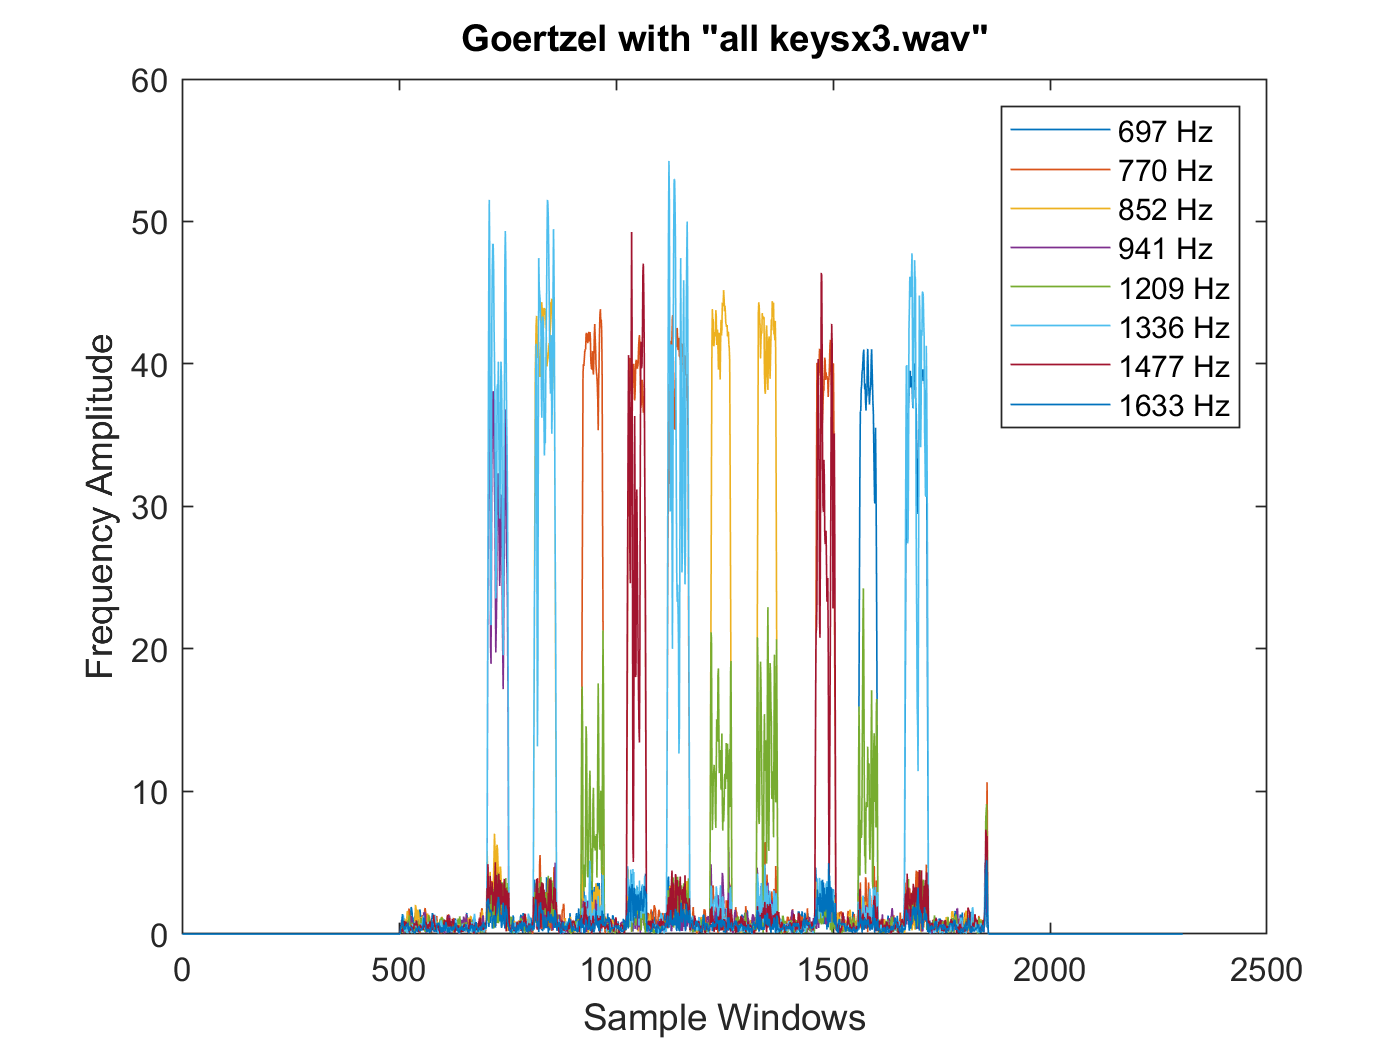

plot(abs(decoded_dfts));
xlabel('Sample Windows')
ylabel('Frequency Amplitude')
title('Goertzel with "all_ keysx3.wav"')
legend('697 Hz', '770 Hz', '852 Hz', '941 Hz', '1209 Hz', '1336 Hz', '1477 Hz', '1633 Hz')